a = 0.01;
b = 0.02;
c = 1;
mu = 2;
par = [a,b,c,mu];
delta_t = 1;
N = 100;
time = delta_t*((1:1:N + 1) - 1)';

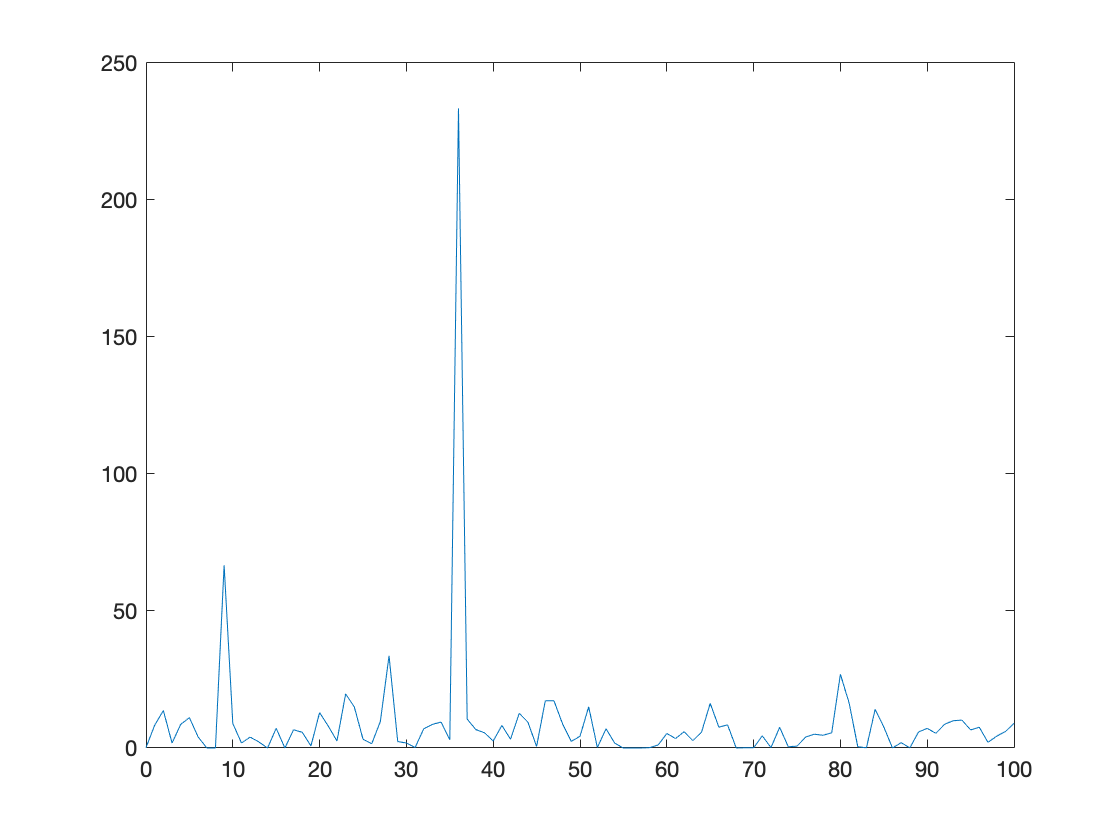

re = simulation_result(N,par,delta_t);
x = re(:,1);
y = re(:,2);
sigma = exp(x);
S = exp(y);
% R = particle_filter(par,delta_t,N,2000,y);
plot(time,S)

% csvwrite('1.csv',Out);

% RNN = csvread('2.csv');
% S_r_pre = RNN(2:102,2);

% R = particle_filter(par,delta_t,N,2000,S_r_pre);
% csvwrite('1.csv',R);